# Practice of robot system toolbox with visulization

Peter Chang 2026/01/22

Example of using DH (standard) to build rigid body tree, also practice from "learning_jackobian" exercise

## Spong's book Example 3.2 Cylindrical Robot base to arm no wrist definition

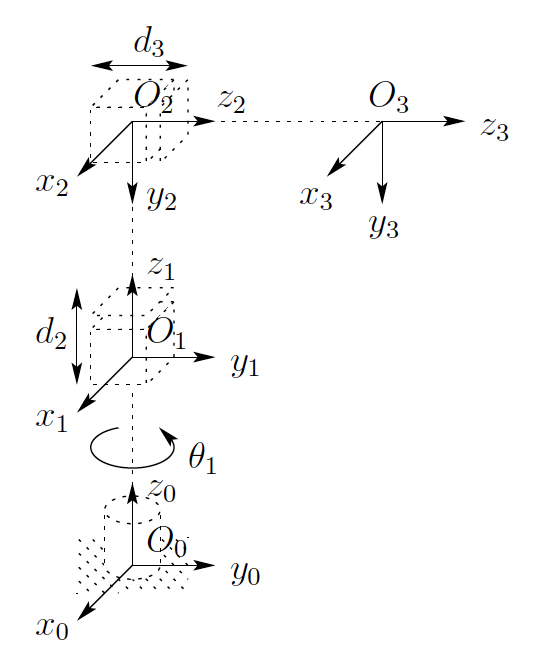

assume that a resonable table-top arm setup, the d-h table from the previous frame assignment shows: c means constant

this meant there are three rigid bodies: link1-revolute, link2-prismatic, link3-prismatic. R-P-P setup.

Asked ChatGPT to learn later assignement on future mass, moment of inertia, center of mass and "geometry" so on.

Now needs to focus on rigid body tree object usage and definition.

% comparison of MATLAB code and Craig's code
% using matlab robotics toolbox to create a rotbot (rigid body tree) object
% recall matlab document: https://www.mathworks.com/help/robotics/ug/build-manipulator-robot-using-kinematic-dh-parameters.html

close all;
clear;
clc

First learn to use rigid body for slow process and test Transform


$$^{parent}T_{child}(q) = ^{parent}T_{joint}\; \underbrace{T_{\text{motion}}(q)}_{\text{about JointAxis}}\; ^{joint}T_{child}$$


% body1 = rigidBody('body1')
% 
% jnt1 = rigidBodyJoint('jnt1','revolute')
% jnt1.HomePosition = pi/4;
% tform = trvec2tform([0.25, 0.25, 0]); % User defined
% setFixedTransform(jnt1,tform);
% body1.Joint = jnt1
% jnt1
% jnt1.JointToParentTransform
% jnt1.ChildToJointTransform

Now there is a joint axis property, and thus the most important part is that where the "joint axis" (always set as [0 0 1] the "imaginary z axis" is located, oriented (!Joint frame!) relatively to the "parent frame". This makes the imaginary rigid body a joint that is either "fliped/twisted" against the previous frame, and relaxing the variable of "prismatic", "revolute" into a random rotation/elongation number in matlab show(robot).

% pre-assign 
th1 = 0;
d2 = .0; 
d3 = .0;

dhparams = [0 0 0.2 th1;0 -deg2rad(90) 0.2+d2 0;0 0 0.2+d3 0]

dhparams =          0         0    0.2000         0
         0   -1.5708    0.2000         0
         0         0    0.2000         0



[nrow, ncol] = size(dhparams);
% create robot tree object
cy_robot = rigidBodyTree;

% Using cell array for rigid body object, another for joint object.
bodies = cell(nrow,1);
joints = cell(nrow,1);

    bodies{1} = rigidBody(['body' num2str(1)]);
    bodies{2} = rigidBody(['body' num2str(2)]);
    bodies{3} = rigidBody(['body' num2str(3)]);

    joints{1} = rigidBodyJoint(['jnt' num2str(1)],"revolute");
    joints{2} = rigidBodyJoint(['jnt' num2str(2)],"prismatic");
    joints{3} = rigidBodyJoint(['jnt' num2str(3)],"prismatic");

First assign all the body names, and the joint names. This is essential that how to dirve all the joints kinematics, later for speed/jacobian and then dynamics. Note joints always move on local [0 0 1] z-axis, with revolute/rotation, and presimatic/elongation either direction.

% iterate through dhparams to put in the cell array
for i = 1:nrow
    setFixedTransform(joints{i}, dhparams(i,:),"dh");
    bodies{i}.Joint = joints{i};    % don't forget this part!!!
    if i == 1 % add first body to base
        addBody(cy_robot,bodies{i},"base")
    else
        addBody(cy_robot,bodies{i},bodies{i-1}.Name)
    end
end

This is the standard way to attach all bodies by 1. setFixedTransform(jointObj, tform). Remeber jointObj is which joint to be "jointToParent" frame (tform) Transformation, setting joint position/orientation (at end of link), relative to the parent (so the last link/joint also at parent link)'s frame. 2. can also do setFixedTransform(jointObj, dpparams, "dh") or setFixedTransform(jointObj, mdpparams, "mdh") for both standard DH (Spong) or modified DH (Craig). 

3. Most important, the book keeping of all the frame {i}, is the user's job, and to follow all the co-incidal orgins as using dh, mdh setFixedTransform is going to "ignore" the parameterized movement (\theta for revolute, d for prismatic). 

showdetails(cy_robot)

--------------------
Robot: (3 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2    prismatic            body1(1)   body3(3)  
   3        body3         jnt3    prismatic            body2(2)   
--------------------


this command is for assuring all bodies and joints are attached in order.

% figure(Name="Plannar model")
% show(robot)
fig1 = figure('Name',"Cylindrical Robot", 'NumberTitle','off', 'WindowStyle','normal');
ax1 = axes('Parent',fig1);
%figure(fig1);

sure way to add a un-embedded figure frame outside of matlab windows gui, and fill both figures..

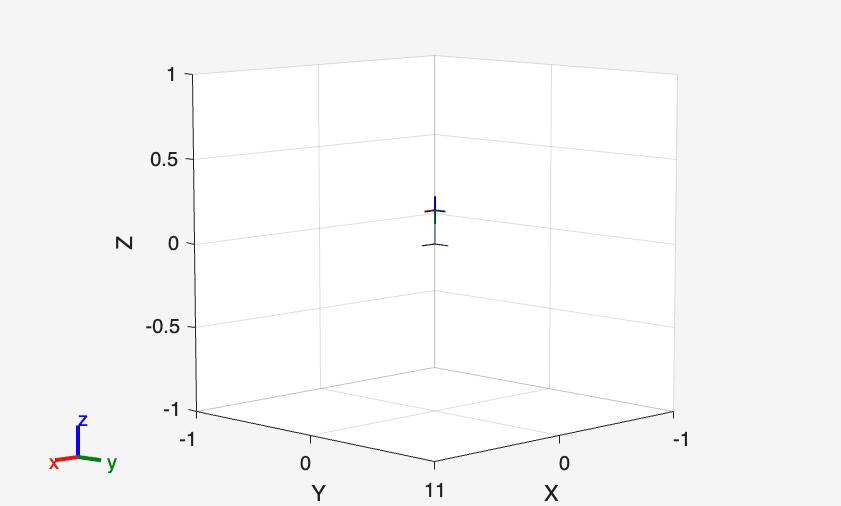

show(cy_robot, 'Parent',ax1,"Frames","on");
axis(ax1,"equal");
grid(ax1,"on");
rotate3d(fig1,'on');

drawnow;

a short snippet for acquireing "q" to get current home configuration of the current body's all frame location and orientation.

% making sure all fig1 is ax1.

special way to add a new figure to move and check the degree of freedom, and move the end effector to show fk/ik, with limited workspace movement.

% figure(Name="Interactive GUI")
% gui = interactiveRigidBodyTree(cy_robot,MarkerScaleFactor=0.5);

Right now this shows a little strange as the three default \theta_a, d_2 and d_3 are all zero but moveable. We need to manyully move (type in a number) them and update the new robot to show all the frames!!

% check q
whos q
q(1).JointPosition = pi/4;
q(2).JointPosition = .5;
q(3).JointPosition = 0.35;

%show(cy_robot, q,"Frames","on")
getJointFrames(cy_robot);

body1 origin = [0.0000 0.0000 0.2000]
body1 direction = [-0.0000 0.0000 -0.0000]
body2 origin = [0.0000 0.0000 0.2000]
body2 direction = [-1.5708 0.0000 -0.0000]
body3 origin = [0.0000 0.0000 0.2000]
body3 direction = [-1.5708 0.0000 -0.0000]


This is how to continously move into the joints, imaging giving timed command and draw window by window.

## using rigid body tree cell to make a mdh dhparameters rigid body with 3 bodies

Using a circle path trajectory (so that the velocity is also continous) in work space, starting point on the radius that is pre-assigned, no need to move to the circle. Using sin/cos and directly the inverse kinematics to pre-assign the location!

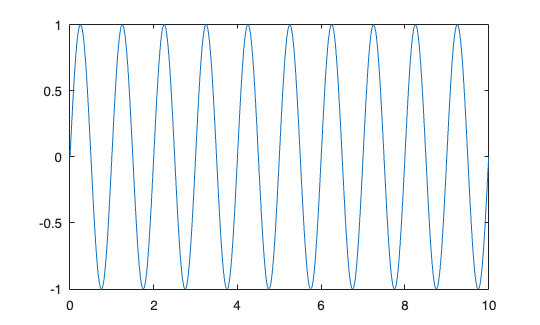

clc;
clear all;
close all;

% New z-planar mDH table using craig's example, for a 2-link robot.
t =linspace(0,10,10001);    % total simulation of 10 seconds, SR 1000 hz, ST 1ms.

f = 1;      % 1 hz (one cycle per second, 1 rps = 60 rpm) likly 10 revolutions

v = sin(2*pi*f*t);   % set velocity at 10 cm/s, so it is a constant velocity using sine

fig2 = figure('Name',"Velocity assigment");
ax2 = axes('Parent', fig2);

plot(ax2, t, v);

making the mdh table

but still needs to be total se3 object 

% with a_1 = 0.5, a_2 = 0.5;
% using theta_1 = pi/3 (param);, theta_2 = pi/4 (param); theta_3 = 0 (fixed);
th1 = pi/3;
th2 = pi/4;
a1 = 0.5;
a2 = 0.5;
th3 = 0;

mdh_param = [0 deg2rad(90) 0 th1; a1 0 0 th2; a2 0 0 th3]

mdh_param =          0    1.5708         0    1.0472
    0.5000         0         0    0.7854
    0.5000         0         0         0



% make sure rigid body cell names and joints are named
bodies = cell(1,3);
joints = cell(1,3);
jtype = {"revolute","revolute","fixed"};

twolink_robot = rigidBodyTree('DataFormat','column','MaxNumBodies',3);

bodies{1} = rigidBody(['body' num2str(1)])

bodies = 1×3 cell array
    {1×1 rigidBody}    {0×0 double}    {0×0 double}


joints{1} = rigidBodyJoint(['jnt' num2str(1)],jtype{1})

joints = 1×3 cell array
    {1×1 rigidBodyJoint}    {0×0 double}    {0×0 double}



% using one fig to plot and practice all the fransform, and make se3
% objects.


## make and show standard frame

assign base frame, so to later affix joint frame 1


% using standard frame with original location and standard orientation,
% plot on base figure
eul = [0 0 0]

eul =      0     0     0


xyz = [0 0 0]

xyz =      0     0     0



eul2tform(eul)  % check tranformation and representations

ans =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


eul2rotm(eul)   % check rotational matrix representations 

ans =      1     0     0
     0     1     0
     0     0     1


eul2quat(eul)   % quaternion representation. remember quaternion is so3

ans =      1     0     0     0



trvec2tform(xyz)

ans =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1



tt = trvec2tform(xyz)*eul2tform(eul)

tt =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


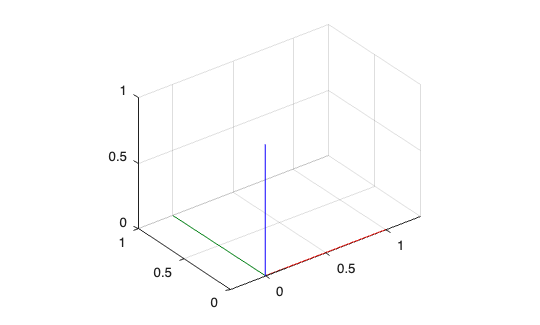


fig3 = figure('Name',"Add frame slowly");
ax3 = axes('Parent',fig3);
hold(ax3, 'on');
grid(ax3, 'on');
axis(ax3, 'equal');

plotTransforms(tform2trvec(tt),tform2quat(tt), 'Parent', ax3);  % base frame

## 1nd frame

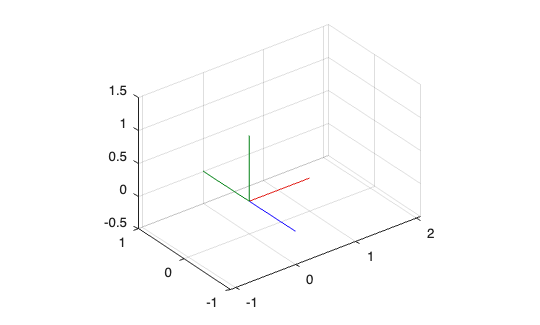

%% moving to next frame manually...
eul = [0 0 pi/2];   % turn about z-axis to 45 degrees
xyz = [0 0 0];      % move along z-axis to point plus one
quat = eul2quat(eul);   % change euler representation into quaternion representation

tt = tt*trvec2tform(xyz)*quat2tform(quat);  % change (homogeneous multiplication transform) to full se3 matrix

plotTransforms(xyz, tform2quat(tt), 'Parent', ax3);     % first frame moved up, use above transfomation

                                                    % NOTE!! tt pre-multiplications!! 
setFixedTransform(joints{1},tt);
bodies{1}.Joint = joints{1};

addBody(twolink_robot,bodies{1},'base');
                                                                                                 % premuliplication

## 2rd frame

% 2nd move to next frame
eul = [0 0 0];
xyz = [0 0 1.5];
quat = eul2quat(eul);

tt = tt*trvec2tform(xyz)*quat2tform(quat)   % moved based on most recent moved tt transform, note tt *=

tt =     1.0000         0         0         0
         0    0.0000   -1.0000   -1.5000
         0    1.0000    0.0000    0.0000
         0         0         0    1.0000


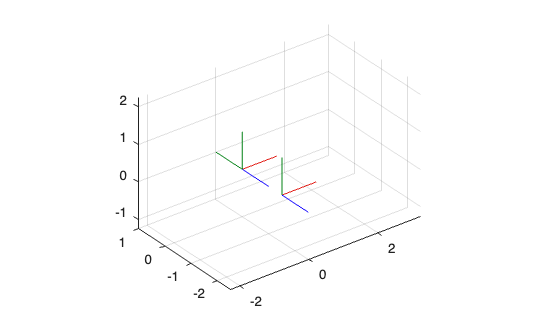


plotTransforms(tform2trvec(tt), tform2quat(tt), 'Parent', ax3);


setFixedTransform(joints{2},tt);
bodies{2}.Joint = joints{2};

addBody(twolink_robot,bodies{2},bodies{1});


## 3rd frame

% 3rd move to frame
eul = [0 0 0];
xyz = [0 0 -1.5];
quat = eul2quat(eul);

tt = tt*trvec2tform(xyz)*quat2tform(quat)   % moved based on most recent moved tt transform, note tt *=

tt =     1.0000         0         0         0
         0    0.0000   -1.0000    1.5000
         0    1.0000    0.0000   -0.0000
         0         0         0    1.0000


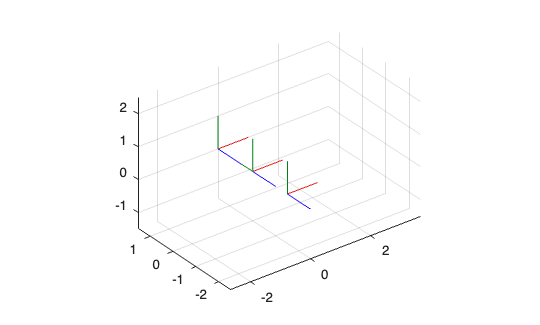


plotTransforms(tform2trvec(tt), tform2quat(tt), 'Parent', ax3);


setFixedTransform(joints{3},tt);

Incorrect number or types of inputs or outputs for function setFixedTransform.

bodies{3}.Joint = joints{3};

addBody(twolink_robot,bodies{3},bodies{2});

% for i = 1:3
%     bodies{i} = rigidBody(['body' num2str(i)]);
%     joints{i} = rigidBodyJoint(['jnt' num2str(i)],jtype{i});
% 
%     setFixedTransform(joints{i}, mdh_param(i,:),'mdh');
%     bodies{i}.Joint = joints{i};
% 
%     if i == 1
%         addBody(twolink_robot,bodies{i},"base")
%     else
%         addBody(twolink_robot,bodies{i},bodies{i-1}.Name)
%     end
% end

% fig4 = figure('Name',"2link Plnar Upright Robot")
% ax4 = show(twolink_robot);

showdetails(twolink_robot);

% getJointFrames(twolink_robot)




## Appendix: Local functions

a smalll function to make and retrive joint frames 

function getJointFrames(robot)

    q = homeConfiguration(robot);

    for name = ["body1","body2","body3"]
        T = getTransform(robot, q, name);
        p = tform2trvec(T);
        rpy = tform2eul(T, "XYZ");   % roll-pitch-yaw (radians)
        fprintf("%s origin = [%.4f %.4f %.4f]\n", name, p(1), p(2), p(3));
        fprintf("%s direction = [%.4f %.4f %.4f]\n", name, rpy(1), rpy(2), rpy(3));
    end

end